%calculate the average probability

R = [-0.0253,  0.0035,  0.0061; ...
         0.0253, -0.0238,  0.0469; ...
         0.0000,  0.0203, -0.0530];

t_long = 5000;
p_avg = expm(R*t_long) * [1;0;0];
error = R* p_avg

error =    1.0e-17 *

   -0.1608
    0.2955
   -0.4155


%calculates the expected autocorrelation

elong_time = 5;
deltaT = 40;
r_emission = [3.5,65,120];
time_steps = 50;
max_delay = 30;
K = 3

K = 3

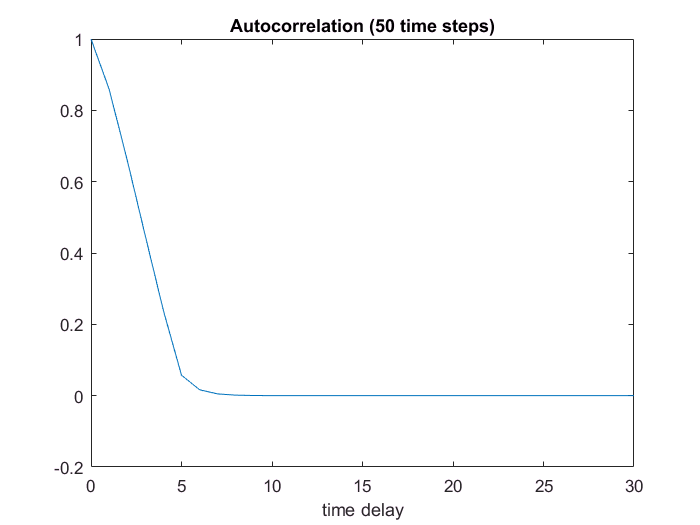


sol = zeros(1,max_delay+1);

%calculates elongation term

elong_coeff = sum(p_avg' .* r_emission*deltaT .* (1 + r_emission*deltaT));
for i = 1:elong_time
    sol(i) = sol(i) + (elong_time - i + 1) * elong_coeff;
end

%calculates dynamics correlation term

expectations = zeros(1,max_delay + elong_time - 1);
for i = 1:(max_delay + elong_time - 1)
    for k = 1:K
        p_delay = zeros(K,1);
        p_delay(k) = 1;
        p_delay = expm(R*deltaT*i)* p_delay;
        expectations(i) = expectations(i) + sum(p_delay' .* r_emission*deltaT) ...
            * r_emission(k) * deltaT * p_avg(k);
    end
end

% adds dynamics correlation to terms where elong_time > time_delay

for i = 1:elong_time
    delay = i - 1;
    if delay >= 1
        for j = 1:delay
            sol(i) = sol(i) + (elong_time - delay + j)*expectations(j);
        end
    end
    for j = 1:(elong_time - delay)
        sol(i) = sol(i) + (elong_time - delay - j)*expectations(j);
    end
    for j = (delay + 1):(elong_time + delay)
        sol(i) = sol(i) + (elong_time + delay - j)*expectations(j);
    end
end

% adds dynamics correlation to terms where elong_time <= time_delay

for i = elong_time:max_delay
    delay = i;
    for j = (1 - elong_time + delay):delay
        sol(delay + 1) = sol(delay+1) + (j + elong_time - delay)*expectations(j);
    end
    for j = (delay+1):(elong_time + delay-1)
        sol(delay+1) = sol(delay+1) + (elong_time + delay - j)*expectations(j);
    end
end

%calculates the mean and subtracts the mean squared from every term

mu = elong_time * sum(p_avg' .* r_emission * deltaT);
sol = sol - mu*mu;
sol = sol / sol(1);

%plots autocorrelation

figure()
plot(0:max_delay, sol);
title("Autocorrelation (50 time steps)");
xlabel("time delay");

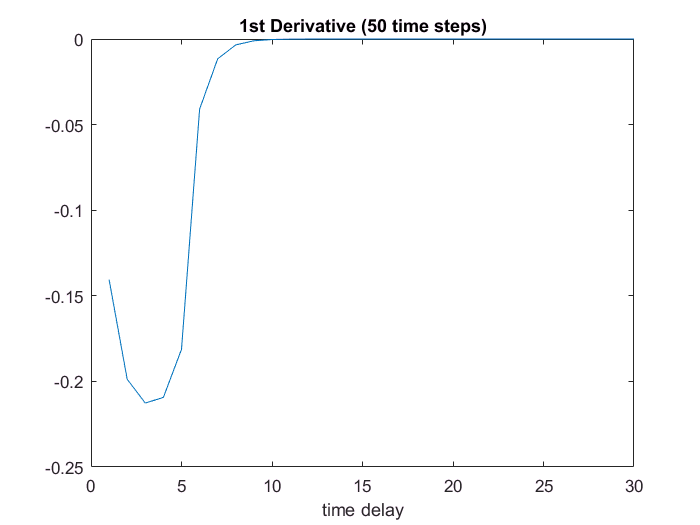


%plots first derivative of autocorrelation

deriv_1st = sol(2:max_delay + 1) - sol(1:max_delay);

figure()
plot(1:max_delay, deriv_1st);
title("1st Derivative (50 time steps)");
xlabel("time delay");

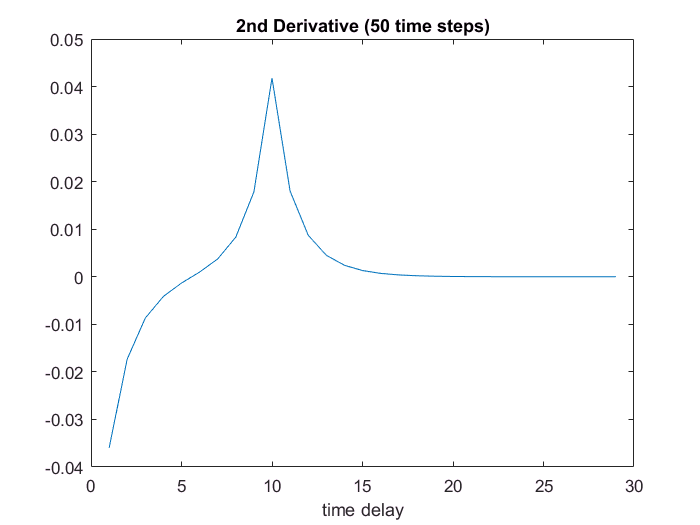


%plots 2nd derivative

deriv_2nd = deriv_1st(2:end) - deriv_1st(1:end - 1);

figure()
plot(1:max_delay-1, deriv_2nd);
title("2nd Derivative (50 time steps)");
xlabel("time delay");